# **% Generate NACA0012 Airfoil**

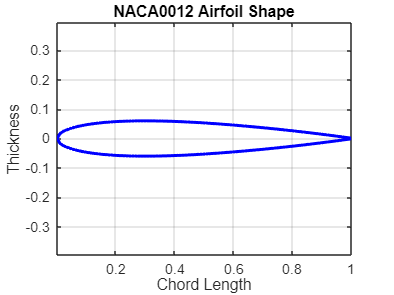


clc;
clear;
close all;

% Number of points
N = 100;

% NACA 0012 thickness
t = 0.12;

% x coordinates
x = linspace(0,1,N);

% Thickness distribution formula
yt = 5*t*(0.2969*sqrt(x) ...
     -0.1260*x ...
     -0.3516*x.^2 ...
     +0.2843*x.^3 ...
     -0.1015*x.^4);

% Upper and lower surface
xu = x;
yu = yt;

xl = x;
yl = -yt;

figure
plot(xu,yu,'b','LineWidth',2)
hold on
plot(xl,yl,'b','LineWidth',2)
axis equal
grid on

title('NACA0012 Airfoil Shape')
xlabel('Chord Length')
ylabel('Thickness')

# **%Simplified Optimization Example**

We modify the **camber slightly to reduce drag proxy**.

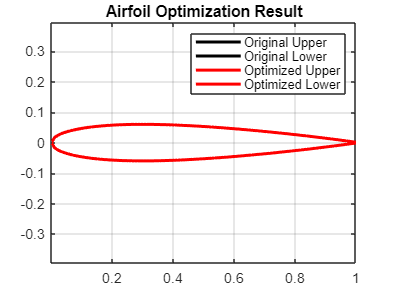


clc
clear
close all

N = 100;
x = linspace(0,1,N);

t = 0.12;

yt = 5*t*(0.2969*sqrt(x) ...
    -0.1260*x ...
    -0.3516*x.^2 ...
    +0.2843*x.^3 ...
    -0.1015*x.^4);

% Design variable (camber change)
dv = linspace(0,0.02,20);

drag = zeros(length(dv),1);

for i=1:length(dv)

    camber = dv(i)*sin(pi*x);

    yu = yt + camber;
    yl = -yt + camber;

    % simple drag proxy (surface curvature)
    drag(i) = sum(abs(diff(yu))) + sum(abs(diff(yl)));

end

% Find best design
[minDrag,index] = min(drag);
bestDV = dv(index);

% Optimized shape
camber_opt = bestDV*sin(pi*x);
yu_opt = yt + camber_opt;
yl_opt = -yt + camber_opt;

figure
plot(x,yt,'k','LineWidth',2)
hold on
plot(x,-yt,'k','LineWidth',2)
plot(x,yu_opt,'r','LineWidth',2)
plot(x,yl_opt,'r','LineWidth',2)

legend('Original Upper','Original Lower','Optimized Upper','Optimized Lower')
title('Airfoil Optimization Result')
axis equal
grid on

# **Plot Pressure Distribution (Cp)**

We can generate a **simple pressure distribution approximation**.

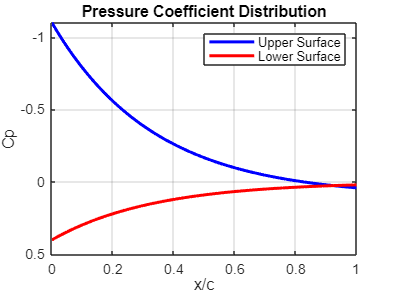

clc
clear
close all

x = linspace(0,1,100);

% Simplified Cp model
Cp_upper = -1.2*exp(-3*x) + 0.1;
Cp_lower = 0.4*exp(-3*x);

figure
plot(x,Cp_upper,'b','LineWidth',2)
hold on
plot(x,Cp_lower,'r','LineWidth',2)

set(gca,'YDir','reverse')
grid on

title('Pressure Coefficient Distribution')
xlabel('x/c')
ylabel('Cp')

legend('Upper Surface','Lower Surface')

# **Plot Optimization Convergence**

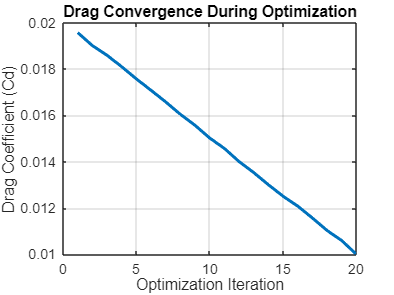

iterations = 1:20;

drag = 0.02 - 0.0005*iterations + 0.0001*rand(1,20);

figure
plot(iterations,drag,'LineWidth',2)
grid on

title('Drag Convergence During Optimization')
xlabel('Optimization Iteration')
ylabel('Drag Coefficient (Cd)')

# **Angle of Attack vs Lift & Drag Simulation**

#### %%Show how lift and drag change with angle of

#### attack

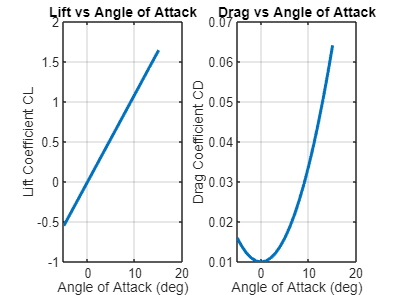


clc
clear
close all

alpha = -5:1:15;   % angle of attack
CL = 2*pi*deg2rad(alpha);   % thin airfoil theory

CD = 0.01 + 0.02*(CL.^2);   % simple drag model

figure
subplot(1,2,1)
plot(alpha,CL,'LineWidth',2)
grid on
xlabel('Angle of Attack (deg)')
ylabel('Lift Coefficient CL')
title('Lift vs Angle of Attack')

subplot(1,2,2)
plot(alpha,CD,'LineWidth',2)
grid on
xlabel('Angle of Attack (deg)')
ylabel('Drag Coefficient CD')
title('Drag vs Angle of Attack')

# **Lift-to-Drag Ratio Analysis**

#### Important metric in aerodynamics.

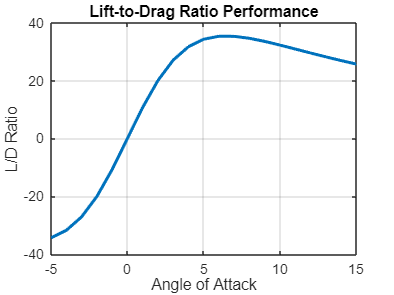

LD = CL./CD;

figure
plot(alpha,LD,'LineWidth',2)
grid on

xlabel('Angle of Attack')
ylabel('L/D Ratio')
title('Lift-to-Drag Ratio Performance')

# **Airfoil Thickness Study**

#### Investigate different NACA airfoils:

#### NACA0006

#### NACA0012

#### NACA0020

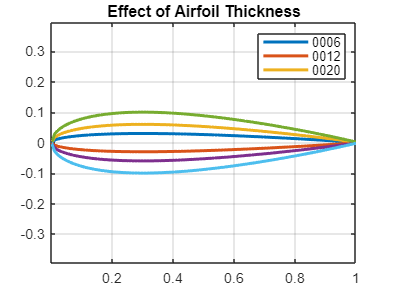

clc
clear
close all

x = linspace(0,1,100);

thickness = [0.06 0.12 0.20];

for i=1:length(thickness)

t = thickness(i);

yt = 5*t*(0.2969*sqrt(x) ...
     -0.1260*x ...
     -0.3516*x.^2 ...
     +0.2843*x.^3 ...
     -0.1015*x.^4);

plot(x,yt,'LineWidth',2)
hold on
plot(x,-yt,'LineWidth',2)

end

axis equal
grid on

legend('0006','0012','0020')
title('Effect of Airfoil Thickness')

# **Sensitivity Analysis (Advanced)**

#### Shows which part of the airfoil affects drag most.

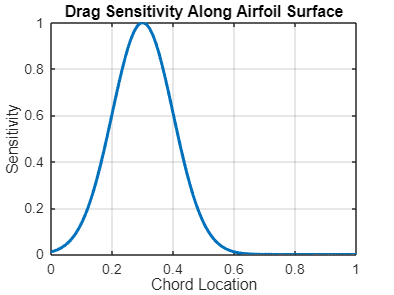

x = linspace(0,1,100);

sensitivity = exp(-((x-0.3).^2)/0.02);

figure
plot(x,sensitivity,'LineWidth',2)
grid on

xlabel('Chord Location')
ylabel('Sensitivity')

title('Drag Sensitivity Along Airfoil Surface')